% usuwanie wartosci skrajnych
%   [wart indx] = max(cond_sym(:,rozmiar));
%   iteracje_sym_bezprzes(indx,rozmiar) = 0;

% warunek stopu
%   while tol(fun(x)) > 0.00001 & i < 200+1

% % wyznaczanie pierw f. kwadratowej
% function [x1 x2] = pierw_f_kwadratowej(mala_macierz)
%     a = 1;
%     b = -(mala_macierz(1,1)+mala_macierz(2,2));
%     c = (mala_macierz(1,1)*mala_macierz(2,2))-(mala_macierz(2,1)*mala_macierz(1,2));
%     
%     x1 = (-b + sqrt(b*b - 4*a*c))/(2*a);
%     x2 = (-b - sqrt(b*b - 4*a*c))/(2*a);
%     if abs(x2) > abs(x1)
%         x1 = x2;
%     end
%    %drugi pierwiastek ze wzorów Viete'a
%     x2 = ((-b)/a) - x1;
% end

start

clc;
clear;
x = linspace(0,15,100);

wykres

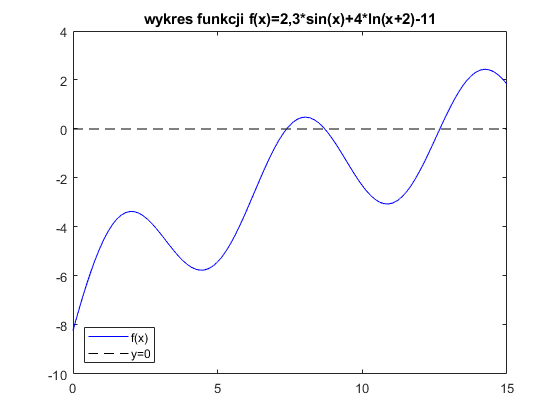

figure
y = wartosc_funkcji(x);
plot(x,y,'b-',[0 15], [0 0], 'k--');
legend({'f(x)', 'y=0'},'Location','southwest');
title('wykres funkcji f(x)=2,3*sin(x)+4*ln(x+2)-11');

oszacowanie miejsc zerowych na podstawie rysunku (skrypt prof Tatjeskiego mowi, zeby estymowac na poodstawie rysunku)

% wartosc_funkcji(7.25)
% wartosc_funkcji(8)
% wartosc_funkcji(9)
% wartosc_funkcji(12.5)

przedzialy poczatkowe

przedzialy = [0 8; 8 10; 10 15];

for i=1:3
    %wybor i-tego przedzialu
    sprawdzenie_przedzialu(przedzialy(i,:));
end

metoda bisekcji

bisekcja(przedzialy)

ans =      0
     0
     0


**funkcje pomocnicze glowne**

metoda bisekcji

function x = bisekcja(przedzialy)
    ilosc_pierwiastkow = size(przedzialy,1);
    x = zeros(ilosc_pierwiastkow);
    x = wektor(x);
    
    for i = 1:ilosc_pierwiastkow
        c = 0;
        while (wartosc_funkcji(c)<0.0001 & (przedzialy(i,2)-przedzialy(i,1)) < 0.01)
            [c przedzialy(i,:)] = polowienie_przedzialu(przedzialy(i,:));
            c
        end
        x(i) = c;
    end
end

polowienie przedzialow dla metody bisekcji

function [c nowy_przedzial] = polowienie_przedzialu(przedzial)
    c = (przedzial(1)+przedzial(2))/2;
    if(sprawdzenie_przedzialu([przedzial(1) c]) == 1)
        nowy_przedzial = [przedzial(1) c]; 
    else
        nowy_przedzial = [c przedzial(2)];
    end
end

**funkcje pomocnicze dodatkowe**

wyznaczenie wyjsc dla podanych x-ow i zadanej funkcji

function y = wartosc_funkcji(x)
    [temp rozmiar_x] = size(x);
    y = zeros(rozmiar_x);
    y = y(:,1);
    for i = 1:rozmiar_x
        y(i,1) = 2.3*sin(x(1,i))+4*log(x(1,i)+2)-11;
    end
end

sprawdzenie czy w podanym przedziale jest miejsce zerowe

function result = sprawdzenie_przedzialu(przedzial)
    if wartosc_funkcji(przedzial(1))*wartosc_funkcji(przedzial(2)) < 0
        result = 1;
    else
        result = 0;
    end
end

wyznaczenie wartosci zer na podstawie miejsc zerowych

function y = tol(x)
    y = max(abs(fun(x)));
end

funkcja wektoryzujaca macierz diagonalna

function w = wektor(A)
    rozmiar = size(A);
    for i = 1:rozmiar
        w(i,1) = A(i,i);
    end
end

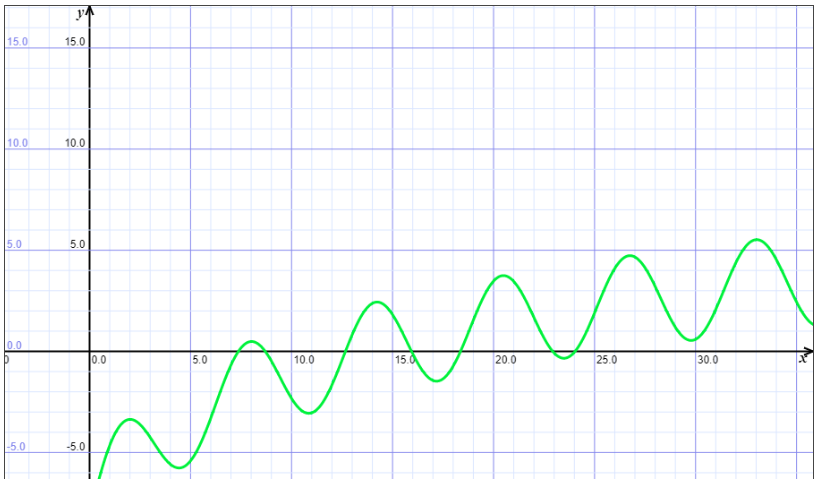

[https://www.matemaks.pl/program-do-rysowania-wykresow-funkcji.html](https://www.matemaks.pl/program-do-rysowania-wykresow-funkcji.html)

2,3*sin(x)+4*log(x+2)-11